# MTH 4800 Numerical Analysis I Programming Assignment 1

## Jarred Maestas

## Problem 1: MATLAB Onramp Certificate

Complete the free MATLAB Onramp assignment at [https://matlabacademy.mathworks.com/](https://matlabacademy.mathworks.com/)

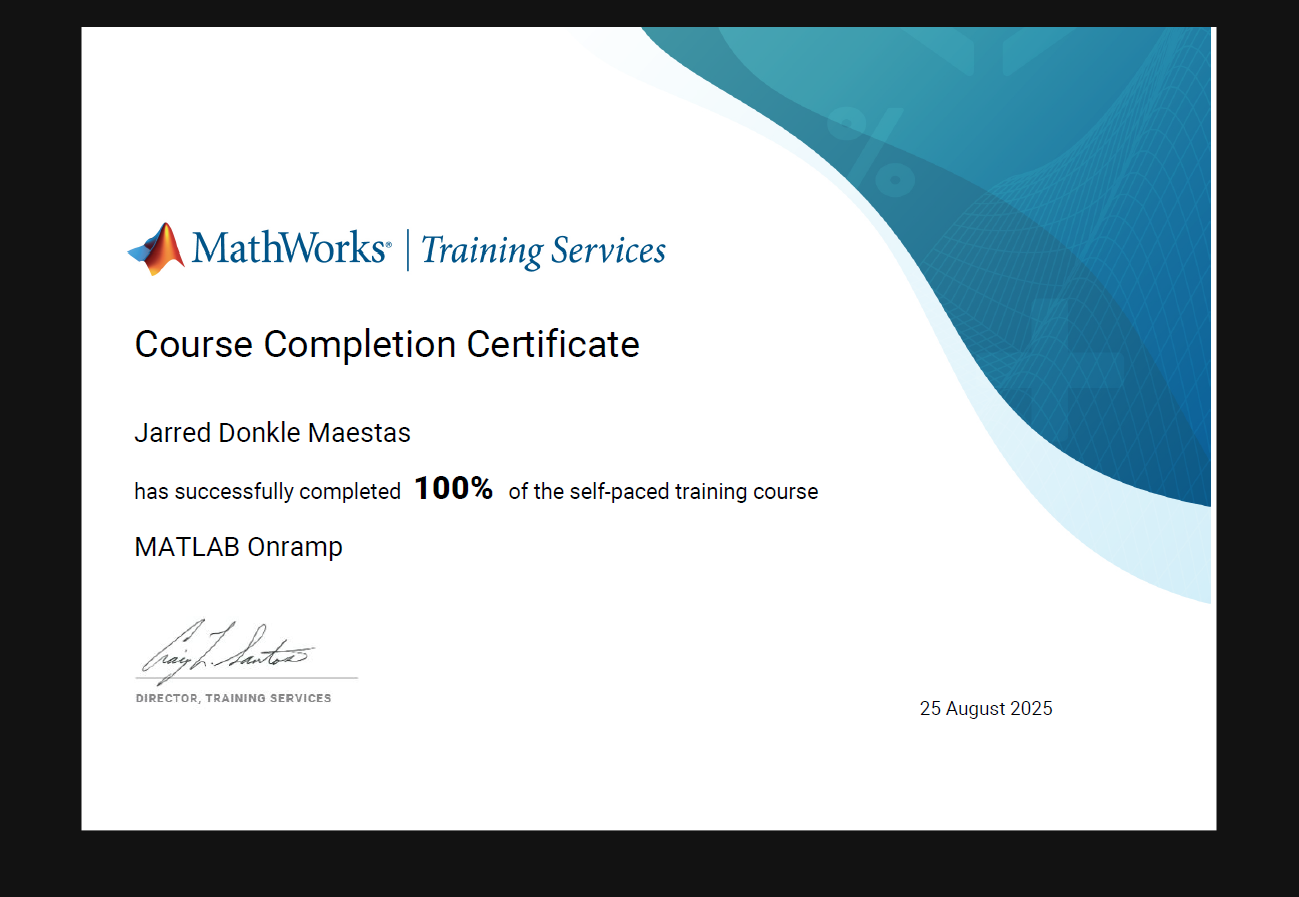

imshow('./certificate.png')

## Problem 2: Basic MATLAB Calculations

Compute sin(π), e^1, set x = 7 and f = 3x - 5

% Calculate sin(π)
sin_pi = sin(pi);
fprintf('sin(π) = %.10f\n', sin_pi);

sin(π) = 0.0000000000



% Calculate e^1
e_to_1 = exp(1);
fprintf('e^1 = %.10f\n', e_to_1);

e^1 = 2.7182818285



% Set x = 7 and calculate f = 3x - 5
x = 7;
f = 3*x - 5;
fprintf('For x = %d: f = 3x - 5 = %d\n', x, f);

For x = 7: f = 3x - 5 = 16


## Comments on Findings

- sin(π) ≈ 0, which is expected since π is a multiple of π so sin ≈ 0

- e^1 ≈ 2.718, which is Euler's number

## Problem 3: Vector Operations

Input vectors a = [2, 3](http://1,) and b = [1, 4](http://2,)

a = [1, 2, 3];
b = [2, 1, 4];

fprintf('\nVector a = [%d, %d, %d]\n', a);


Vector a = [1, 2, 3]


fprintf('Vector b = [%d, %d, %d]\n', b);

Vector b = [2, 1, 4]


## Problem 3a: Dot Product

dot_product = dot(a, b);
fprintf('\n3a) Dot product a·b = %d\n', dot_product);


3a) Dot product a·b = 16


## Problem 3b: Cross Product

cross_product = cross(a, b);
fprintf('\n3b) Cross product a×b = [%d, %d, %d]\n', cross_product);


3b) Cross product a×b = [5, 2, -3]


## Problem 3c: Size of Vector a

size_a = size(a);
fprintf('Size of vector a = [%d, %d]\n', size_a);

Size of vector a = [1, 3]


fprintf('Length of vector a = %d\n', length(a));

Length of vector a = 3


## Problem 3d: Sum of Vector b

sum_b = sum(b);
fprintf('Sum of vector b = %d\n', sum_b);

Sum of vector b = 7


## Problem 3e: Matrix Multiplication and Linear System

A = [4, 3, 5; 2, 1, 7; 8, 1, 3];
disp(A);

     4     3     5
     2     1     7
     8     1     3



% Multiply A with vector a
Aa = A * a';
disp(Aa);

    25
    25
    19



% Solve linear system Ax = b
x_solution = A \ b';
disp(x_solution);

    0.5000
         0
         0




% Verify the solution
verification = A * x_solution;
fprintf('Verification A*x = [%.4f, %.4f, %.4f]\n', verification);

Verification A*x = [2.0000, 1.0000, 4.0000]


fprintf('Original b = [%d, %d, %d]\n', b);

Original b = [2, 1, 4]


## Problem 4: Single Graph with Multiple Functions

Plot x, sin(x), cos(x), and tan(x) from -π ≤ x ≤ π

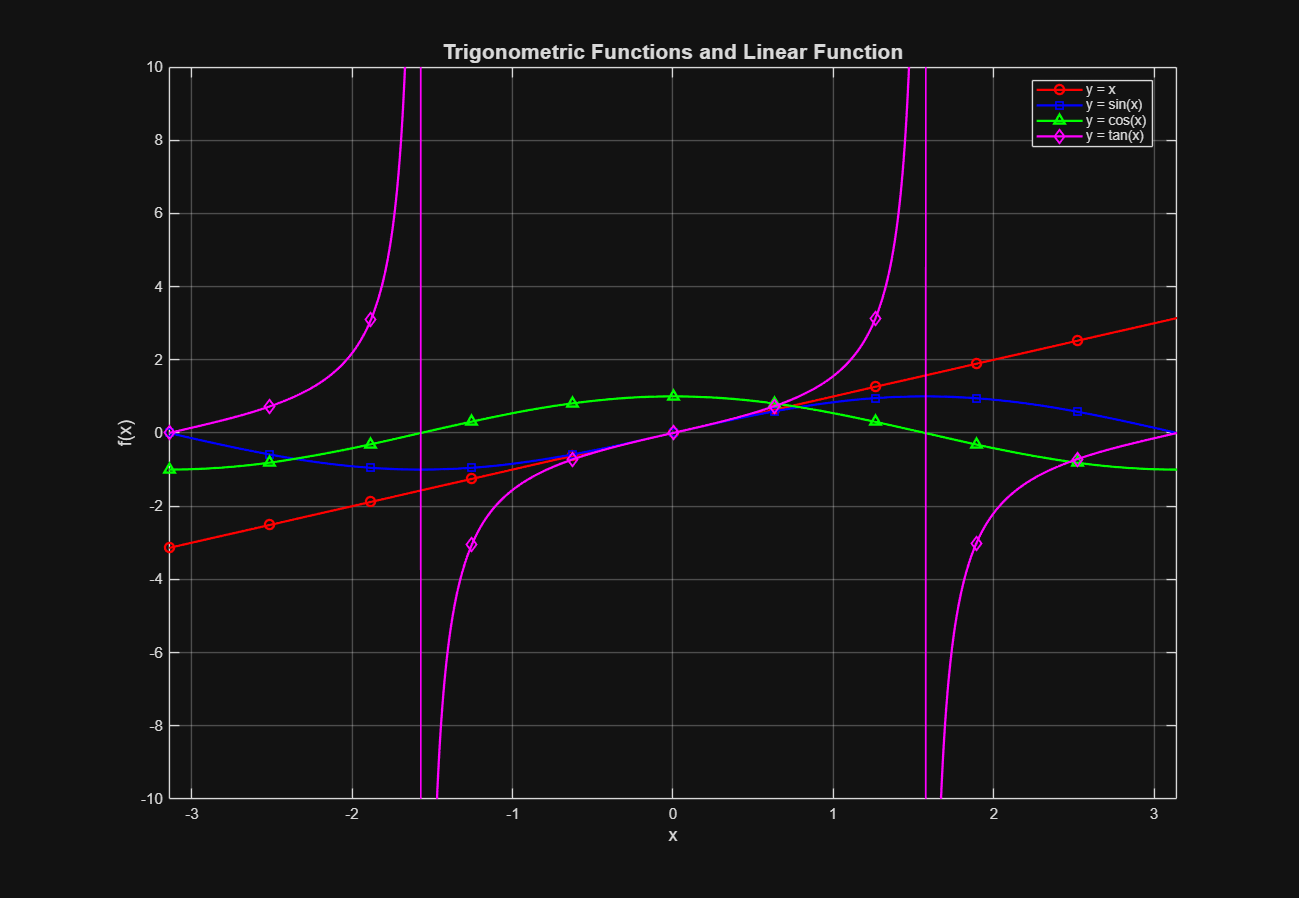

figure(1);
x_range = linspace(-pi, pi, 1000);

plot(x_range, x_range, 'r-o', 'MarkerIndices', 1:100:length(x_range), ...
     'DisplayName', 'y = x', 'LineWidth', 1.5);
hold on;
plot(x_range, sin(x_range), 'b-s', 'MarkerIndices', 1:100:length(x_range), ...
     'DisplayName', 'y = sin(x)', 'LineWidth', 1.5);
plot(x_range, cos(x_range), 'g-^', 'MarkerIndices', 1:100:length(x_range), ...
     'DisplayName', 'y = cos(x)', 'LineWidth', 1.5);
plot(x_range, tan(x_range), 'm-d', 'MarkerIndices', 1:100:length(x_range), ...
     'DisplayName', 'y = tan(x)', 'LineWidth', 1.5);

ylim([-10, 10]);
xlim([-pi, pi]);
title('Trigonometric Functions and Linear Function', 'FontSize', 14);
xlabel('x', 'FontSize', 12);
ylabel('f(x)', 'FontSize', 12);
legend('show', 'Location', 'best');
grid on;
hold off;

## Problem 5: Subplot Version

Plot the same graphs on their own axes in the same window

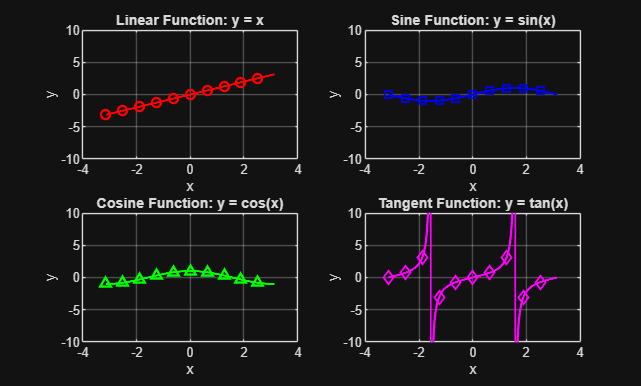

figure(2);

% Plot y = x
subplot(2, 2, 1);
plot(x_range, x_range, 'r-o', 'MarkerIndices', 1:100:length(x_range), 'LineWidth', 1.5);
title('Linear Function: y = x');
xlabel('x');
ylabel('y');
ylim([-10, 10]);
grid on;

% Plot sin(x)
subplot(2, 2, 2);
plot(x_range, sin(x_range), 'b-s', 'MarkerIndices', 1:100:length(x_range), 'LineWidth', 1.5);
title('Sine Function: y = sin(x)');
xlabel('x');
ylabel('y');
ylim([-10, 10]);
grid on;

% Plot cos(x)
subplot(2, 2, 3);
plot(x_range, cos(x_range), 'g-^', 'MarkerIndices', 1:100:length(x_range), 'LineWidth', 1.5);
title('Cosine Function: y = cos(x)');
xlabel('x');
ylabel('y');
ylim([-10, 10]);
grid on;

% Plot tan(x)
subplot(2, 2, 4);
plot(x_range, tan(x_range), 'm-d', 'MarkerIndices', 1:100:length(x_range), 'LineWidth', 1.5);
title('Tangent Function: y = tan(x)');
xlabel('x');
ylabel('y');
ylim([-10, 10]);
grid on;

## Problem 6: Fibonacci Numbers - First Algorithm!

## Problem 6a: Fibonacci Function

Write a program to generate Fibonacci numbers

function fib_vector = fibonacci_generator(n)
    % Initialize the vector with zeros
    fib_vector = zeros(1, n);
    
    % Handle base cases
    if n >= 1
        fib_vector(1) = 0;  % First Fibonacci number is 0
    end
    if n >= 2
        fib_vector(2) = 1;  % Second Fibonacci number is 1
    end
    
    % Generate remaining Fibonacci numbers using the recurrence relation
    % F(n) = F(n-1) + F(n-2)
    for i = 3:n
        fib_vector(i) = fib_vector(i-1) + fib_vector(i-2);
    end
end

## Problem 6b: First 15 Fibonacci Numbers

fib_15 = fibonacci_generator(15);
disp('First 15 Fibonacci numbers:');

First 15 Fibonacci numbers:


disp(fib_15);

     0     1     1     2     3     5     8    13    21    34    55    89   144   233   377



## Problem 6c: 42nd Fibonacci Number

Generate the 42nd Fibonacci number without displaying the entire vector

fib_42_vector = fibonacci_generator(42);
fib_42_value = fib_42_vector(42);

disp(['The 42nd Fibonacci number is: ', num2str(fib_42_value)]);

The 42nd Fibonacci number is: 165580141
